# OlinOval.mlx is a simulation of a planetary rover

This code simulates a wheeled autonomous planetary rover performing multiple smissions on the Olin Oval

- It takes desired location waypoints as inputs

- It delivers a moving map simulation of the rover traversing the Oval as an output

Written by CJ Hilty, February 2022. Revision A. Based on Revision A of OlinOval.mlx by Betsy Yu and Frank Olin, 2021.

clc     % clear command window
clear   % clear MATLAB workspace

### **Set up robot control system** (code that runs once)

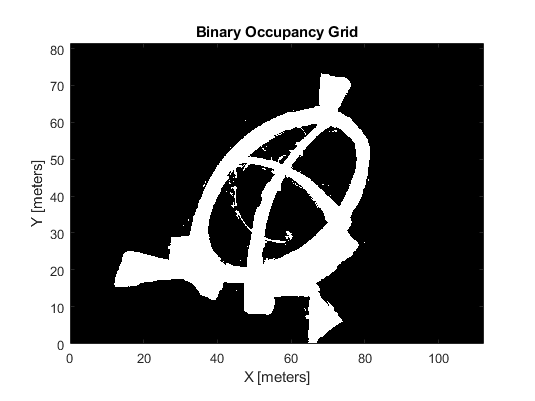

img=imread('OlinOvalMap.png');          % load oval image (from local directory)
grayimage=im2gray(img);                 % convert to grayscale
bwimage=grayimage < 0.5;                % convert to black and white
MapOfOval = binaryOccupancyMap(bwimage,10); % convert to a binary occupancy map in meters
show(MapOfOval);                        % show map

%Inflate map so robot can be treated as a point.
%Assume robot is 0.25m square.
MapOfOvalInflated = copy(MapOfOval);    % make a copy without overwriting original data
inflate(MapOfOvalInflated,0.25);        % dilate the map to accommodate robot size

% To prevent unexpected display glitches in the livescript window,
% create a free-floating figure for the maps to display simulation updates
ovalTrack = figure('name','ovalTrack','NumberTitle','off','Visible','on');
figure(ovalTrack);                      % go to ovalTrack figure for next plot
    show(MapOfOvalInflated)             % show new map in a figure window
    grid on; grid minor;                % set plot properties

Create a lidar-based map of the world that will be filled as the Rover drives around the Oval

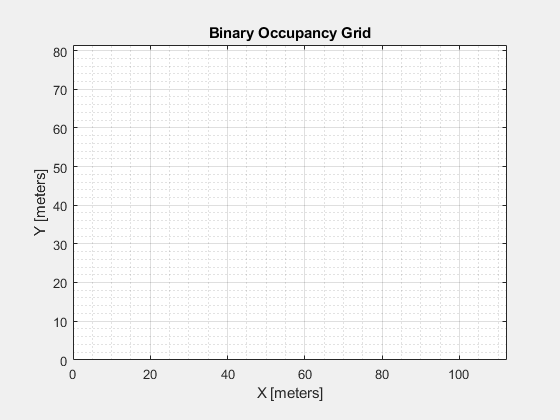

% Create an empty map as the same dimensions as the MapOfOval occupancy map
[mapdimx,mapdimy] = size(bwimage);      % find and store size of map
lidarMap = binaryOccupancyMap(mapdimx,mapdimy,10,'grid');% make empty map of same size

% create another free-floating figure for map updates to avoid livescript display glitches
RoverLidarScan = figure('name','RoverLidarScan','NumberTitle','off','Visible','on');
    show(lidarMap);                     % display the figure
    grid on; grid minor;                % set grid options


% note: map figure should be blank to start and it will be populated later.

Create a simulated differential drive robot rover. Inputs are robot vehicle speed and heading.

diffDriveRover = differentialDriveKinematics('vehicleInputs','VehicleSpeedHeadingRate');

Create a pure pursuit rover controller (this controller generates the required speed and heading values needed to follow a path. It can incorporate a desired linear velocity (m/s) and maximum angular velocity (radians/sec)

RoverController = controllerPurePursuit('DesiredLinearVelocity',2,'MaxAngularVelocity',3);

Create a simulated 360° LiDAR range sensor for the rover. It should have a **max range of 40 meters**.

- The rangeSensor function has scarce documentation. On the function right-click> help or f1 is useful.

- The simulated lidar will simulate range readings from a LiDAR based on position and location on a map.

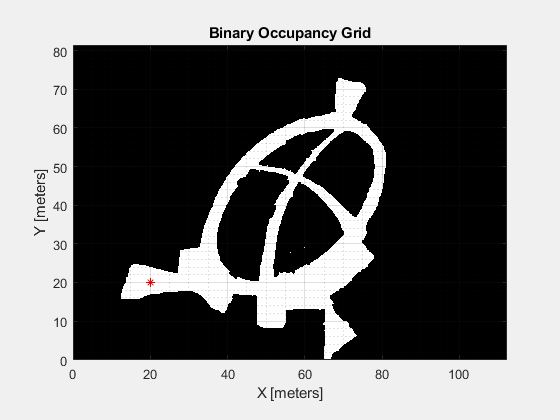

lidar = rangeSensor;        % create a simulated rangeSensor object
lidar.Range = [0.5,40];     % set minimum and maximum range of sensor
testPose = [20 20 pi/2];    % set an initial test position for lidar

% Plot the test spot for the LiDAR scan on the Olin Oval occupancy map
figure(ovalTrack)           % select the OvalTrack map figure for drawing
hold on;
plot(20,20, 'r*');          %plot robot position in Oval
hold off;

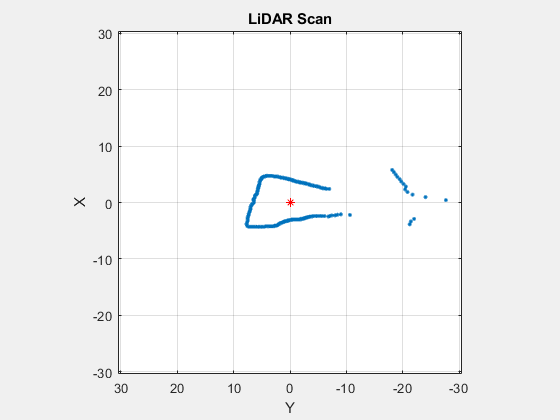


% Generate a LiDAR test scan from the test position defined above in testPose
    [ranges,angles] = lidar(testPose, MapOfOvalInflated);
    scan = lidarScan(ranges, angles);

% Visualize the test lidar scan from the robot's coordinate system
% by creating a new free-standing figure with the robot at the center
% and plotting the local LiDAR scan on that figure.
    LocalLidarMap = figure('Name','LocalLidarMap','NumberTitle','off','Visible','on');
    figure(LocalLidarMap);
    plot(scan);
    hold on;
    plot(0,0,'r*');
    hold off;    

path = [20 20; 30 20; 38 20; 35 25; 38 40; 45 50; 58 60];% matrix of waypoints
%path = [20 20; 25 25]; % short matrix of waypoints to test stopping precision
% Plot the waypoints as a path on the OlinOvalMap occupancy map
figure(ovalTrack);                          % select the ovalTrack figure
hold on;
plot(path(:,1),path(:,2),'o-');             % Plot the points from the matrix of waypoints
hold off;

Use the waypoints in the **path** variable as the waypoints the Pure Pursuit controller will follow

RoverController.Waypoints = path;       %Set rover waypoints

Set the initial pose and final goalWayPoint location from points in the **path** variable, then create global variables for storing the current pose and an index for tracking loop count.

initRoverPose = [path(1,1) path(1,2) pi/2] % Store initial location and orientation, aka pose

initRoverPose =    20.0000   20.0000    1.5708


goalWayPoint = [path(end,1) path(end,2)]'  % why "'"? > Sets target end waypoint

goalWayPoint =     58
    60


sampleTime = 0.10;                          % Sample time (seconds)
t = 0:sampleTime:100;                       % Time array
robotPoses = zeros(3,length(t));            % Preallocate arrray for robot Poses
robotPoses(:,1) = initRoverPose';           % Add initial robot pose to robot Poses array
r = rateControl(1/sampleTime)

r =   rateControl with properties:

         DesiredRate: 10
       DesiredPeriod: 0.1000
       OverrunAction: 'slip'
    TotalElapsedTime: 0.0027
          LastPeriod: NaN


reset(r);
tolerance = 0.1;                            % In meters, the minimum distance from the final waypoint to finish routine

Arrange figure windows for easy viewing, ask the operator if they are ready and give start options

iptwindowalign(ovalTrack,'right',RoverLidarScan,'left')

iptwindowalign(RoverLidarScan,'bottom',LocalLidarMap,'top')
iptwindowalign(ovalTrack,'right',LocalLidarMap,'left')

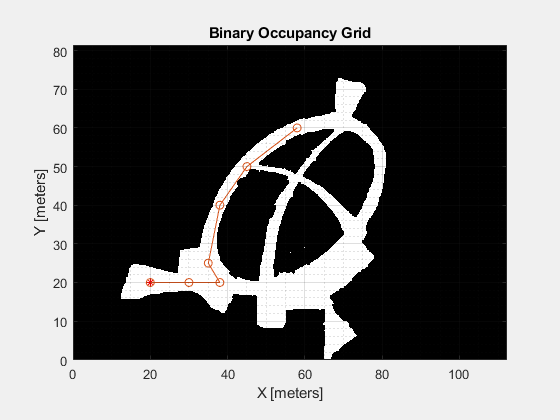

runRover = 1

runRover = input('Press CTRL + C to abort, or\nWhen ready, press 1 and then ENTER to run robot.\n')

### **Run robot control loop **(code that runs over and over)

controlIndex = 1;                           % creates a loop control to limit number of total loops
while(controlIndex < numel(t))              % Loop for number of timesteps in operating procedure
    position = robotPoses(:,controlIndex)'; % gets current robot x,y, and angle
    roverLocation = position(1:2);          % extracts rover x and y from position variable
    %End the loop if rover has reached goal waypoint within tolerance
    dist = norm(goalWayPoint' - roverLocation);    
    if (dist < tolerance)                   % if robot has reached goal
        break;                              % breaks out of entire control loop
    end

    %SENSE: collects LiDAR data from the simulated environment occupancy map 
    [ranges,angles] = SENSE(position, MapOfOvalInflated, lidarMap, RoverLidarScan, LocalLidarMap, lidar);
    
    %THINK: computes and stores next target position
    [roverX, roverY, robotPoses] = THINK(robotPoses, diffDriveRover, RoverController, sampleTime, controlIndex);
    
    %ACT: commands the actuators by writing on the Occupancy Map
    ACT(roverX, roverY, ovalTrack);

    controlIndex = controlIndex + 1;        % increments loop index
    waitfor(r);                             % pauses loop until sampleTime has passed
end
beep                                        % Play a sound when actions are completed
keep = input("Goal position reached!\nDistance from the final waypoint was " + dist + " meters.\nPress 1 and then ENTER to keep figure windows\nor press ENTER to close them for a clean desktop.")


keep =

     []



if keep == 1
    % Do nothing
else
    close all;                              % Close all figure windows for a clean desktop
end

### **Robot Functions** (store this code's local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions.

**Functions that are neither sense, think, nor act** (leaving room but typically scarce)

% function CONTROL_LOOP_OUTPUT(time)
%     disp('robot running, press cntrl-c to stop')
%     fprintf('The loop time is %d, \n',time)
% end

**Sense Functions **(Store all sense-related local functions here)

function [ranges, angles] = SENSE(position, mapOfTrack, blankLidarMap, fig_lidarMap, fig_localLidarPlot, lidar)
% SENSE scans the reference map using the range sensor and the current pose.
% This simulates normal range readings for driving in an unknown environment.
% SENSE also updates the lidar map with the range readings.
% inputs: rover position, mapOfTrack, lidarMap, figure to plot global lidar, figure to plot local lidar, sensor name
% outputs: lidar ranges and angles in local coordinate system
% CJ Hilty 2022 Rev A.
    [ranges, angles] = lidar(position, mapOfTrack);                         % Gets available ranges and angles for LiDAR in simulated position
    scan = lidarScan(ranges,angles);                                        % Simulates LiDAR scan
    validScan = removeInvalidData(scan,'RangeLimits',[0,lidar.Range(2)]);   % Removes values beyond the max range
    insertRay(blankLidarMap,position,validScan,lidar.Range(2));             % Plots LiDAR scan on global map

    figure(fig_lidarMap);                                                   % Selects the global LiDAR map
        hold on;
        show(blankLidarMap);                                                % Displays changes made
        grid on;
        grid minor;
        hold off;
    figure(fig_localLidarPlot);
    plot(scan);                                                             % Plots LiDAR scan onto local map
    hold on;
    plot(0,0,'r*')                                                          % Plots robot position on local map
    hold off
end

**Think Functions **(Store all think-related local functions here)

function [roverX, roverY, poses] = THINK(poses, diffDrive, ppControl, sampleTime, loopIndex)
% THINK gets control commands from the pure pursuit controller to drive to
% next waypoint. Calculates derivative of robot motion based on control
% commands.
% Inputs: Robot poses Array, diffDrive dynamics, loop sampleTime, loop index.
% Outputs: roverX, roverY, updated Robot poses Array
% CJ Hilty 2022 Rev A

    %Run Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = ppControl(poses(:,loopIndex)); % Calculates velocity and angular velocity

    % Forward discrete integration that converts velocities to positions
    vel = derivative(diffDrive, poses(:,loopIndex), [vRef wRef]);
    poses(:,loopIndex + 1) = poses(:,loopIndex) + vel*sampleTime;

    % Store updated rover location for return
    roverX = poses(1, loopIndex + 1);
    roverY = poses(2, loopIndex + 1);
end

**Act Functions **(Store all act-related local functions here)

function ACT(roverX, roverY, fig_testTrack)
% ACT plots the updated robot pose based on the results of THINK.
% inputs: Robot's X and Y coordinates, figure to plot robot in.
% no outputs.
% CJ Hilty 2022 Rev A
    figure(fig_testTrack)
    hold on;
    plot(roverX, roverY, 'b*');
    hold off;
end